**Challenge Problem 1.1**

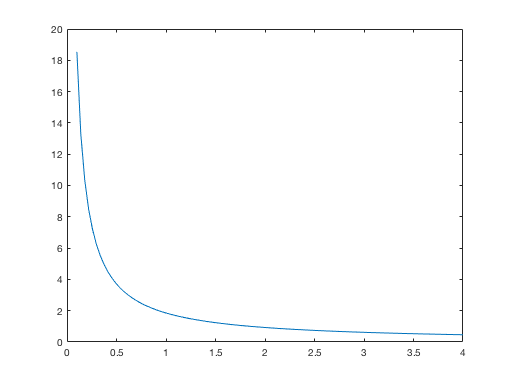

a = linspace(.1,4,100);
f= @(a,x)(2./sqrt(2*(a.^4-x.^4)));

b=zeros(1,100);
for i=1:100
    element=a(i);
    x=linspace(0,element,100);
    c = integral(@(x) f(element,x),0,element);
    b(i) = c; 
end
plot(a,b)